# Muscle frequency by localmax

% Choose Folder to process

    dirin = uigetdir(title="Select Folder to Process");
    filelist = dir(fullfile(dirin, "*.csv"));

    allHistosum = []; % One Histosum row per csv file (ie individual image)
    allBins = []; % One bins row per csv file

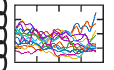

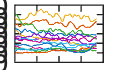

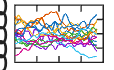

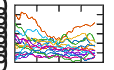

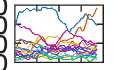

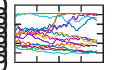

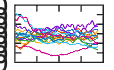

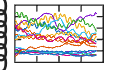


for f = 1:length(filelist)
    filein = fullfile(filelist(f).folder, filelist(f).name);

    T = readtable(filein, 'VariableNamingRule',"preserve");

    tablecol = size(T, 2);

    linein = [];

    j = 1;
    for i = 1:2:tablecol
        linein{j,1} = table2array(T(:,i));
        linein{j,2} = table2array(T(:,i + 1));
        
        linein{j,3} = sum(~isnan(linein{j,2})); % size of measured line in pixels
        j = j +1;
    end
    
    deltax = table2array(T(2,1))-table2array(T(1,1));
    d1 = table2array(T(2,1));
    d2 = table2array(T(1,1));
    linesizes = [];
    for i = 1:size(linein, 1)
        linesizes(i,1) = linein{i,3}.*deltax; % line size in microns
    end

    % *************
    % Smooth the lines
    % *************
    smdata20 = [];
    % smgreen100 = [];
    
    for i = 1:size(linein, 1);
        smdata20{i,1} = smooth(linein{i,2}, 20);
    % smgreen100(:,i) = smooth(wtgreen(:,i), 100);
    end
    
    % smgreen = smdata20 - smgreen100;

    figure();
    for i = 1:size(linein,1);
        plot(smdata20{i,1});
    hold on
    end
    hold off

    % *************
    % Get maxima points
    % *************
    fluormax = [];
    
    for i = 1:size(linein, 1);
        fluormax{i,1} = islocalmax(smdata20{i,1}, 1);
    end
    
    % greenmax = islocalmax(wtgreen, 1);

    maxlocs = [];
    maxdists = [];
    
    bins = (1:1:80) * 0.05; % deltax; 
    disthisto = [];
    
    for i = 1:size(fluormax, 1)
        maxlocs{i,1} = linein{i,1}(fluormax{i,1});
        maxdists{i,1} = diff(maxlocs{i,1});
        disthisto(:,i) = histcounts(maxdists{i,1}, bins);
    end

    % *************
    % Scale histogram counts by length of line they originate from
    % *************
    disthistoscaled = [];
    
    for i = 1:size(linesizes, 1)
        disthistoscaled(:,i) = disthisto(:,i)/linesizes(i,1); %normalize to length of line drawn
    end
    
    histosum = sum(disthistoscaled, 2)./size(linesizes,1); %normalize to number of lines drawn


    figure();
    plot(bins(1:end-1), histosum)
    xlabel("Distance between Peaks (micron)")
    ylabel("Fraction of peaks/micron")
    ylim([0 .12])
    xlim([0 4])
   

## Fraction Sarcomeric

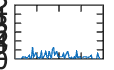

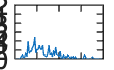

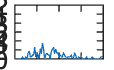

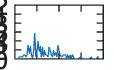

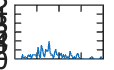

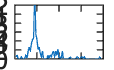

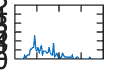

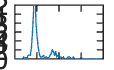

  % Sarcomeric region for myosin 0.6 to 1.2 microns (bins 10 to 24), for actin 1.75 to 2.05
  % microns (bins 35 to 41). 
  % This build is customized for this specific dataset, based on the Josh Plots.
  
  sarcregion = zeros(size(bins, 2)-1, 1);
  sarcregion([10:24, 35:41],1) = 1;
  sarcregion = logical(sarcregion);
  meansarcregion = mean(histosum(sarcregion));
  meannotsarc = mean(histosum(~sarcregion));
    
  sarcfraction = sum(histosum(sarcregion))/sum(histosum); %sum of the sarcomeric region as a fraction of total;
  

   save([filein(1:end-4), '.mat'], 'bins', 'histosum', 'disthistoscaled','meansarcregion','meannotsarc', 'sarcfraction', '-mat')

end 

## SarcFraction Binning

    %Version 3, based on SarcBin code by Joy-El Talbot, updated by Jared Talbot, Josh Kelley, Emily Tomak.
    % *** Run this on the .mat outputs from freq_bypeak*.mlx script. ***
 
    filelist = dir(fullfile(dirin, "*.mat"));
   
    % Define and create output folder

    filename = datestr(datetime("today"), "yyyy-mmm-dd");
    filename = strcat(filename, "_SarcFraction");

    processedFiles = []; % to store for future reproducibility

    % pre-define storage space needed 

    MeanSarcomeric = nan(length(filelist), 1);
    NonSarcomericMean = nan(length(filelist), 1);
    SarcomericFraction = nan(length(filelist), 1);

   for f = 1:length(filelist)
      
       load(fullfile(filelist(f).folder, filelist(f).name));

        MeanSarcomeric(f) = meansarcregion
        NonSarcomericMean (f) = meannotsarc
        SarcomericFraction (f) = sarcfraction

      processedFiles = [processedFiles; convertCharsToStrings(filelist(f).name)]; % store processed filenames

   end

MeanSarcomeric =     0.0080
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0042
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4226
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0080
    0.0195
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0042
    0.0035
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4226
    0.6833
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0080
    0.0195
    0.0112
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0042
    0.0035
    0.0042
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4226
    0.6833
    0.5064
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0080
    0.0195
    0.0112
    0.0171
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0042
    0.0035
    0.0042
    0.0043
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4226
    0.6833
    0.5064
    0.6066
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0080
    0.0195
    0.0112
    0.0171
    0.0086
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0042
    0.0035
    0.0042
    0.0043
    0.0050
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4226
    0.6833
    0.5064
    0.6066
    0.4020
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0080
    0.0195
    0.0112
    0.0171
    0.0086
    0.0261
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0042
    0.0035
    0.0042
    0.0043
    0.0050
    0.0020
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4226
    0.6833
    0.5064
    0.6066
    0.4020
    0.8327
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0080
    0.0195
    0.0112
    0.0171
    0.0086
    0.0261
    0.0170
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0042
    0.0035
    0.0042
    0.0043
    0.0050
    0.0020
    0.0038
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4226
    0.6833
    0.5064
    0.6066
    0.4020
    0.8327
    0.6342
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0080
    0.0195
    0.0112
    0.0171
    0.0086
    0.0261
    0.0170
    0.0304
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0042
    0.0035
    0.0042
    0.0043
    0.0050
    0.0020
    0.0038
    0.0017
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4226
    0.6833
    0.5064
    0.6066
    0.4020
    0.8327
    0.6342
    0.8734
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0080
    0.0195
    0.0112
    0.0171
    0.0086
    0.0261
    0.0170
    0.0304
    0.0168
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0042
    0.0035
    0.0042
    0.0043
    0.0050
    0.0020
    0.0038
    0.0017
    0.0042
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4226
    0.6833
    0.5064
    0.6066
    0.4020
    0.8327
    0.6342
    0.8734
    0.6066
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0080
    0.0195
    0.0112
    0.0171
    0.0086
    0.0261
    0.0170
    0.0304
    0.0168
    0.0259
       NaN
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0042
    0.0035
    0.0042
    0.0043
    0.0050
    0.0020
    0.0038
    0.0017
    0.0042
    0.0033
       NaN
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4226
    0.6833
    0.5064
    0.6066
    0.4020
    0.8327
    0.6342
    0.8734
    0.6066
    0.7543
       NaN
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0080
    0.0195
    0.0112
    0.0171
    0.0086
    0.0261
    0.0170
    0.0304
    0.0168
    0.0259
    0.0153
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0042
    0.0035
    0.0042
    0.0043
    0.0050
    0.0020
    0.0038
    0.0017
    0.0042
    0.0033
    0.0022
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4226
    0.6833
    0.5064
    0.6066
    0.4020
    0.8327
    0.6342
    0.8734
    0.6066
    0.7543
    0.7307
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0080
    0.0195
    0.0112
    0.0171
    0.0086
    0.0261
    0.0170
    0.0304
    0.0168
    0.0259
    0.0153
    0.0261
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0042
    0.0035
    0.0042
    0.0043
    0.0050
    0.0020
    0.0038
    0.0017
    0.0042
    0.0033
    0.0022
    0.0031
       NaN
       NaN
       NaN


SarcomericFraction =     0.4226
    0.6833
    0.5064
    0.6066
    0.4020
    0.8327
    0.6342
    0.8734
    0.6066
    0.7543
    0.7307
    0.7624
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0080
    0.0195
    0.0112
    0.0171
    0.0086
    0.0261
    0.0170
    0.0304
    0.0168
    0.0259
    0.0153
    0.0261
    0.0310
       NaN
       NaN


NonSarcomericMean =     0.0042
    0.0035
    0.0042
    0.0043
    0.0050
    0.0020
    0.0038
    0.0017
    0.0042
    0.0033
    0.0022
    0.0031
    0.0024
       NaN
       NaN


SarcomericFraction =     0.4226
    0.6833
    0.5064
    0.6066
    0.4020
    0.8327
    0.6342
    0.8734
    0.6066
    0.7543
    0.7307
    0.7624
    0.8325
       NaN
       NaN


MeanSarcomeric =     0.0080
    0.0195
    0.0112
    0.0171
    0.0086
    0.0261
    0.0170
    0.0304
    0.0168
    0.0259
    0.0153
    0.0261
    0.0310
    0.0378
       NaN


NonSarcomericMean =     0.0042
    0.0035
    0.0042
    0.0043
    0.0050
    0.0020
    0.0038
    0.0017
    0.0042
    0.0033
    0.0022
    0.0031
    0.0024
    0.0009
       NaN


SarcomericFraction =     0.4226
    0.6833
    0.5064
    0.6066
    0.4020
    0.8327
    0.6342
    0.8734
    0.6066
    0.7543
    0.7307
    0.7624
    0.8325
    0.9420
       NaN


MeanSarcomeric =     0.0080
    0.0195
    0.0112
    0.0171
    0.0086
    0.0261
    0.0170
    0.0304
    0.0168
    0.0259
    0.0153
    0.0261
    0.0310
    0.0378
    0.0350


NonSarcomericMean =     0.0042
    0.0035
    0.0042
    0.0043
    0.0050
    0.0020
    0.0038
    0.0017
    0.0042
    0.0033
    0.0022
    0.0031
    0.0024
    0.0009
    0.0020


SarcomericFraction =     0.4226
    0.6833
    0.5064
    0.6066
    0.4020
    0.8327
    0.6342
    0.8734
    0.6066
    0.7543
    0.7307
    0.7624
    0.8325
    0.9420
    0.8688


MeanSarcomeric =     0.0080
    0.0195
    0.0112
    0.0171
    0.0086
    0.0261
    0.0170
    0.0304
    0.0168
    0.0259
    0.0153
    0.0261
    0.0310
    0.0378
    0.0350


NonSarcomericMean =     0.0042
    0.0035
    0.0042
    0.0043
    0.0050
    0.0020
    0.0038
    0.0017
    0.0042
    0.0033
    0.0022
    0.0031
    0.0024
    0.0009
    0.0020


SarcomericFraction =     0.4226
    0.6833
    0.5064
    0.6066
    0.4020
    0.8327
    0.6342
    0.8734
    0.6066
    0.7543
    0.7307
    0.7624
    0.8325
    0.9420
    0.8688


MeanSarcomeric =     0.0080
    0.0195
    0.0112
    0.0171
    0.0086
    0.0261
    0.0170
    0.0304
    0.0168
    0.0259
    0.0153
    0.0261
    0.0310
    0.0378
    0.0350


NonSarcomericMean =     0.0042
    0.0035
    0.0042
    0.0043
    0.0050
    0.0020
    0.0038
    0.0017
    0.0042
    0.0033
    0.0022
    0.0031
    0.0024
    0.0009
    0.0020


SarcomericFraction = 18×1
    0.4226
    0.6833
    0.5064
    0.6066
    0.4020
    0.8327
    0.6342
    0.8734
    0.6066
    0.7543
    0.7307
    0.7624
    0.8325
    0.9420
    0.8688


MeanSarcomeric = 18×1
    0.0080
    0.0195
    0.0112
    0.0171
    0.0086
    0.0261
    0.0170
    0.0304
    0.0168
    0.0259
    0.0153
    0.0261
    0.0310
    0.0378
    0.0350


NonSarcomericMean = 18×1
    0.0042
    0.0035
    0.0042
    0.0043
    0.0050
    0.0020
    0.0038
    0.0017
    0.0042
    0.0033
    0.0022
    0.0031
    0.0024
    0.0009
    0.0020


SarcomericFraction = 18×1
    0.4226
    0.6833
    0.5064
    0.6066
    0.4020
    0.8327
    0.6342
    0.8734
    0.6066
    0.7543
    0.7307
    0.7624
    0.8325
    0.9420
    0.8688



    % build final table for export...

    results = table(processedFiles, MeanSarcomeric, NonSarcomericMean, SarcomericFraction);

    % CSV export of results table

    writetable(results, fullfile(dirin, strcat(filename, ".csv")));
